yaw_imu = unwrap(imu_d.IMUorientationz);

Complementary equation

alpha = 0.02;
angle = zeros(length(yaw_gyro),1);
hp = zeros(length(yaw_gyro),1);
lp = zeros(length(yaw_gyro),1);
angle(1)=0;
hp(1) = (alpha)*(angle(1) + yaw_gyro(1));
lp(1) = (1-alpha)*(yaw_a(1));
angle(1) = hp(1) + lp(1);
for i = 2:length(yaw_gyro)
    lp(i) = (1-alpha)*(yaw_a(i));
    hp(i) = (alpha)*(angle(i-1) + yaw_gyro(i));
    angle(i) = hp(i) + lp(i);
end

Plotting filter outputs

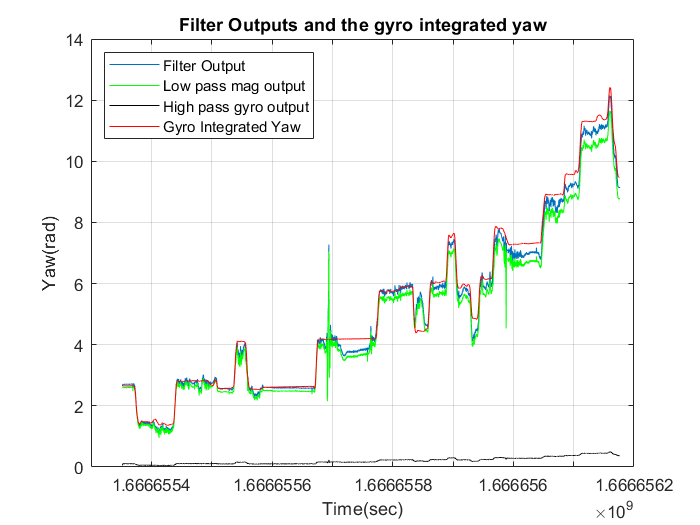

plot(time,angle)
grid on
hold on
plot(time, lp, 'g')
plot(time, hp,'k')
plot(time, yaw_gyro,'r')
legend("Filter Output","Low pass mag output","High pass gyro output","Gyro Integrated Yaw","Location","northwest")
xlabel("Time(sec)")
ylabel("Yaw(rad)")
title("Filter Outputs and the gyro integrated yaw")
hold off